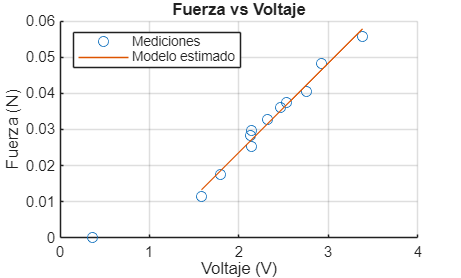

T = readtable('Calibración.xlsx');
Fuerza = T.Var2(1:12);
Voltaje = T.Var1(1:12);
p = polyfit(Voltaje(1:end-1), Fuerza(1:end-1), 1);
y_fit = polyval(p, Voltaje(1:end-1));
figure;
scatter(Voltaje, Fuerza); grid on;
hold on
plot(Voltaje(1:end-1), y_fit)
xlabel('Voltaje (V)');
ylabel('Fuerza (N)');
legend('Mediciones', 'Modelo estimado', 'Location', "northwest");
title('Fuerza vs Voltaje');

% Leer archivo de datos (tab separado, sin encabezado)
datos = ('Friccion.log');

fid = fopen(datos, 'r');
data = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);
lines = data{1};

% Inicializar vectores
angle = [];
time = [];

% Expresión regular para capturar ángulo y tiempo
pattern = 'Angle:\s*([\d.]+)\s+Tiempo:\s*(\d+)';

for i = 1:length(lines)
    line = lines{i};
    tokens = regexp(line, pattern, 'tokens');
    if ~isempty(tokens)
        % Extraer valores como número
        angle_val = str2double(tokens{1}{1});
        time_val = str2double(tokens{1}{2});
        
        % Guardar
        angle(end+1) = angle_val;
        time(end+1) = time_val;
    end
end

lastIndex = find(diff(angle) ~= 0, 1, 'last') + 1;
angle = angle(1:lastIndex)-angle(lastIndex)*ones(1,lastIndex);
time = time(1:lastIndex);

% Convertir a vectores columna
angle = angle(:);
time = time(:);
% Convertir unidades
t = time / 1000;                     
angle_rad = deg2rad(angle);   

[t_u, idx] = unique(t);               % Tiempo sin duplicados
angle_u = angle_rad(idx);
Ts = median(diff(t_u));                % Estimar paso uniforme
t_disc = t_u(1):Ts:t_u(end);    
angle_disc = interp1(t_u, angle_u, t_disc);

% Estimar parámetros desde picos medidos 
[pks, locs] = findpeaks(angle_u, t_u);
A = pks(1:4);   % Picos
Td = locs(2)-locs(1);     % Periodo entre picos en s

delta_vals = log(A(1:end-1) ./ A(2:end));
delta = mean(delta_vals);
zeta = delta/sqrt((2*pi)^2 + delta^2);
omega_d = 2*pi/Td;
omega_n = omega_d/sqrt(1 - zeta^2);

fprintf('Parámetros estimados:\n');

Parámetros estimados:


fprintf('zeta     = %.5f\n', zeta);

zeta     = 0.07164


fprintf('omega_n  = %.5f rad/s\n', omega_n);

omega_n  = 8.01447 rad/s


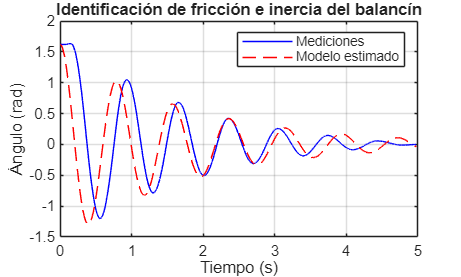


% Construir modelo en espacio de estados 
A = [0      1;
    -omega_n^2  -2*zeta*omega_n];
B = [0; 0];     % Entrada nula (respuesta libre)
C = [1 0];
D = 0;

sys = ss(A, B, C, D);  % Modelo de segundo orden
% Simulación con condiciones iniciales
angle0 = angle_disc(1);
x0 = [angle0; 0];      % [ángulo inicial; velocidad inicial]
u = zeros(size(t_disc));
y_sim = lsim(sys, u, t_disc, x0);

% Graficar comparación 
figure;
plot(t_disc, angle_disc, 'b'); hold on;
plot(t_disc, y_sim, 'r--');
xlabel('Tiempo (s)');
ylabel('Ángulo (rad)');
legend('Mediciones', 'Modelo estimado');
title('Identificación de fricción e inercia del balancín');
grid on;

WL = 0.08;
WR = 0.03;
a = 0.1235*0.72;
b = 0.06916;
c = 0.02514;
Tot_M = WL*b-WR*c;
J = Tot_M/omega_n^2*0.82;        % Momento de inercia (kg·m^2)
B = J*2*zeta*omega_n*3.5;       % Fricción Viscosa (kg·m^2/s)
BJ = B/J;
TotJ = Tot_M/J;
aJ = a/J;
MotC = 0.0247;              % Constante motor (N/V)
deadZ = 0.36;

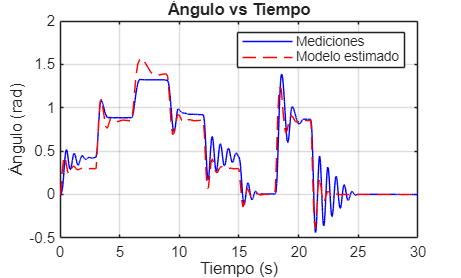

% Leer todas las líneas del archivo
lines = readlines(['Motor.log']);

% Expresión regular para buscar: t: xxx ms, ángulo: yyy.yy
expr = 't:\s*(\d+)\s*ms,\s*ángulo:\s*([-+]?[0-9]*\.?[0-9]+)';

% Aplicar expresión a cada línea
matches = regexp(lines, expr, 'tokens');

% Filtrar líneas válidas: deben tener exactamente 2 datos
matches = matches(~cellfun(@isempty, matches));  % Eliminar vacíos
matches = matches(cellfun(@(x) numel(x{1}) == 2, matches));  % Solo las válidas

% Convertir a arrays numéricos
t_i = cellfun(@(x) str2double(x{1}{1}), matches) / 1000;   % Tiempo en segundos
angle_i = deg2rad(cellfun(@(x) str2double(x{1}{2}), matches)); % Ángulo en grados
lastAngle = find(diff(angle_i) ~= 0, 1, 'last') + 1;
idx_ini = find(t_i >= 2.5, 1);  % Primer índice con t ≥ 2.5
angle_i = angle_i(idx_ini:lastAngle)-angle_i(lastAngle)*ones(lastAngle-idx_ini+1,1);
t_i = t_i(idx_ini:lastAngle)-t_i(idx_ini)*ones(lastAngle-idx_ini+1,1);    

% Graficar para verificar
figure;
plot(t_i, angle_i, 'b'); grid on;
hold on
plot(out.angulo.time, out.angulo.signals.values, "r--")
xlabel('Tiempo (s)');
ylabel('Ángulo (rad)');
xlim([0,30])
legend('Mediciones', 'Modelo estimado');
title('Ángulo vs Tiempo');

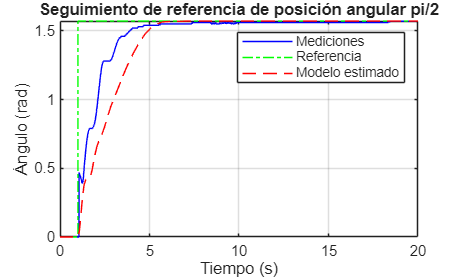

% Leer todas las líneas como texto
lines = readlines('PID.log');

time_expr = '(\d{2}):(\d{2}):(\d{2})\.(\d{3})';
data_expr = 'Raw:\s*(\d+)\s+Angulo:\s*([-+]?[0-9]*\.?[0-9]+)\s+Error:\s*([-+]?[0-9]*\.?[0-9]+)\s+Señal:\s*([-+]?[0-9]*\.?[0-9]+)';

% Inicializar listas
time_sec = [];
raw = []; angle_PID = []; error = []; signal = [];

for i = 1:length(lines)
    line = lines(i);

    % Extraer tiempo
    time_tokens = regexp(line, time_expr, 'tokens');
    if isempty(time_tokens)
        continue;
    end
    t = time_tokens{1};
    t_s = str2double(t{1})*3600 + str2double(t{2})*60 + str2double(t{3}) + str2double(t{4})/1000;

    % Extraer datos
    data_tokens = regexp(line, data_expr, 'tokens');
    if isempty(data_tokens) || numel(data_tokens{1}) ~= 4
        continue;
    end
    d = data_tokens{1};

    % Guardar
    time_sec(end+1) = t_s;
    raw(end+1)      = str2double(d{1});
    angle_PID(end+1)    = str2double(d{2});
    error(end+1)    = str2double(d{3});
    signal(end+1)   = str2double(d{4});
end

% Reescalar tiempo para que comience en 0
t = time_sec - time_sec(1);
idx_fin = find(out.voltaje.time >= 20, 1);  % Primer índice con t ≥ 20;
idx_in = find(out.voltaje.time >= 1, 1);
Ts = median(diff(t));             % Paso de muestreo
N_delay = round(1 / Ts); 
angle_shifted = [zeros(1, N_delay), angle_PID(1:end-N_delay)];
error_shifted = [zeros(1, N_delay), error(1:end-N_delay)];
voltage_shifted = [zeros(1, N_delay), signal(1:end-N_delay)];

% Graficar
figure;
plot(t, angle_shifted, 'b'); grid on; hold on;
plot(out.reference.time(1:idx_fin), out.reference.signals.values(1:idx_fin), "g-.")
plot(out.angulo.time(1:idx_fin), out.angulo.signals.values(1:idx_fin), "r--")
xlabel('Tiempo (s)');
ylabel('Ángulo (rad)');
xlim([0 20])
legend('Mediciones', "Referencia", 'Modelo estimado');
title('Seguimiento de referencia de posición angular pi/2');

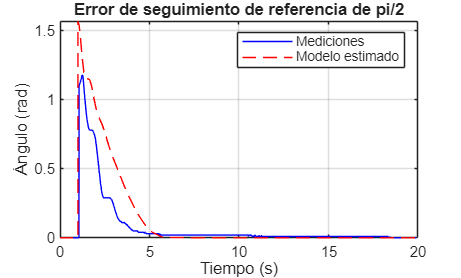


figure;
plot(t, error_shifted, 'b'); grid on; hold on;
plot(out.angulo.time(1:idx_fin), out.error.signals.values(1:idx_fin), "r --")
xlabel('Tiempo (s)');
ylabel('Ángulo (rad)');
xlim([0 20])
legend("Mediciones", 'Modelo estimado');
title('Error de seguimiento de referencia de pi/2');

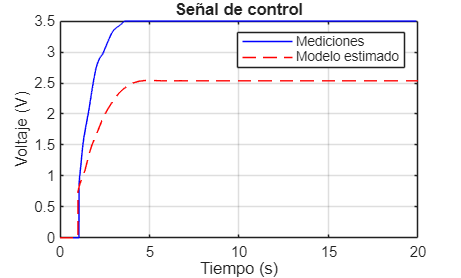


figure;
plot(t, voltage_shifted, 'b'); grid on; hold on;
plot(out.voltaje.time(1:idx_fin), out.voltaje.signals.values(1:idx_fin), 'r--'); grid on;
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
xlim([0 20])
legend("Mediciones", 'Modelo estimado');
title('Señal de control');

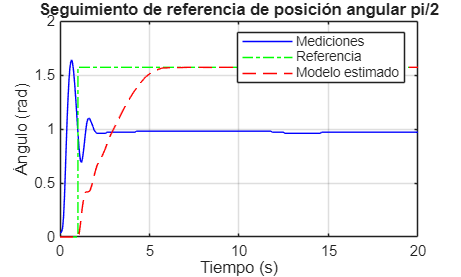

% Leer archivo de texto
lines = readlines('PID_Corrected.log');

% Expresión regular para extraer los datos
expr = 't:\s*(\d+)\s+Angulo:\s*([-+]?[0-9]*\.?[0-9]+)\s+Error:\s*([-+]?[0-9]*\.?[0-9]+)\s+Señal:\s*([-+]?[0-9]*\.?[0-9]+)';

% Aplicar expresión regular a cada línea
tokens = regexp(lines, expr, 'tokens');

% Filtrar las coincidencias válidas
tokens = tokens(~cellfun(@isempty, tokens));

% Extraer cada columna como vector numérico
t_ms   = cellfun(@(x) str2double(x{1}{1}), tokens);  % Tiempo en ms
angle  = cellfun(@(x) str2double(x{1}{2}), tokens);  % Ángulo en grados
error  = cellfun(@(x) str2double(x{1}{3}), tokens);  % Error
signal = cellfun(@(x) str2double(x{1}{4}), tokens);  % Señal

% Convertir tiempo a segundos
t = t_ms / 1000;
Ts = median(diff(t));           
N_delay = round(1 / Ts);
%voltage_shifted = [zeros(1, N_delay), signal(1:end-N_delay)];

figure;
plot(t, angle, 'b'); grid on; hold on;
plot(out.reference.time(1:idx_fin), out.reference.signals.values(1:idx_fin), "g-.")
plot(out.angulo.time(1:idx_fin), out.angulo.signals.values(1:idx_fin), "r--")
xlabel('Tiempo (s)');
ylabel('Ángulo (rad)');
xlim([0 20])
legend('Mediciones', "Referencia", 'Modelo estimado');
title('Seguimiento de referencia de posición angular pi/2');

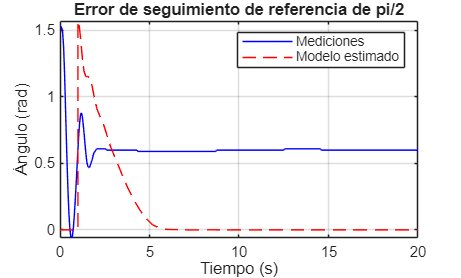


figure;
plot(t, error, 'b'); grid on; hold on;
plot(out.angulo.time(1:idx_fin), out.error.signals.values(1:idx_fin), "r --")
xlabel('Tiempo (s)');
ylabel('Ángulo (rad)');
xlim([0 20])
legend("Mediciones", 'Modelo estimado');
title('Error de seguimiento de referencia de pi/2');

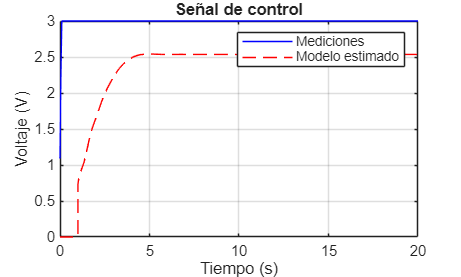


figure;
plot(t, signal, 'b'); grid on; hold on;
plot(out.voltaje.time(1:idx_fin), out.voltaje.signals.values(1:idx_fin), 'r--'); grid on;
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
xlim([0 20])
legend("Mediciones", 'Modelo estimado');
title('Señal de control');